# create timetable from gdt file

## loading the file and extracting the table 

clear
%gdt
options = detectImportOptions('ANON_19810211.GDT', 'FileType','text');
T = readtable('ANON_19810211.GDT', options); 

%edf
edfFile1 = edfread('ANONCapno edf export -1.edf');
edfFile2 = edfread('HT capno.edf');
edfFile3 = edfread('GD capno.edf');
edfFile4 = edfread('WP capno.edf');
display('loadinf file: done');

loadinf file: done


## removing NaN values

%gdt
T.PaCO2(isnan(T.PaCO2)) = 0; %replace Nan values with 0 so they dont get removed in next step
gdtfile = T(~any(ismissing(T),2),:);%remove all rows that have missing value or NaN. now we only have the table remaining.
display('removing NaN: done');

removing NaN: done


## samplingTime and samplePeriod

%gdt
gdtDuration = seconds(duration(gdtfile.Time, 'InputFormat','mm:ss'));%convert to duration
gdtSamplePeriod = round(mean(diff(gdtDuration)));%difference between the samples and we take the mean of that
gdtSampleRate = 1/gdtSamplePeriod;
% edf
edfDuration = seconds(duration(edfFile1.("Record Time")));
edfSamplePeriod = round(mean(diff(edfDuration)));
edfSampleRate = 1/edfSamplePeriod;
display('initializing vars: done');

initializing vars: done


## convert gdt table to timetable

gdtfile.Time=[];%remove Time collumn
Time=transpose(seconds(0:gdtSamplePeriod:(height(gdtfile)-1)*gdtSamplePeriod ));%create new time collumn
gdtTimeTable=table2timetable(gdtfile,'RowTimes',Time);
display('converting to timetables: done');

converting to timetables: done


## Fourier transform and plots 

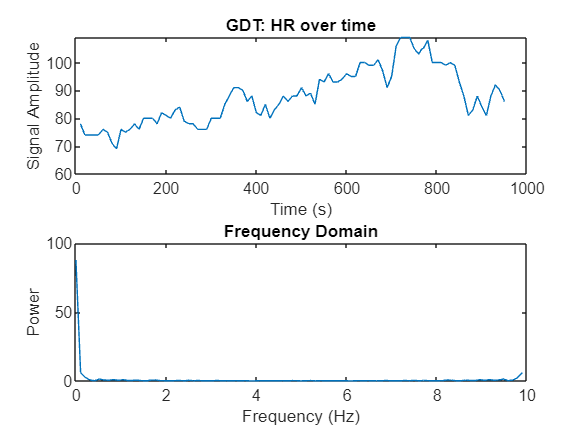

%gdt
signalGdt = gdtfile.HR; %the signal you want to convert
nGdt = length(signalGdt);%signalLength
freqRangeGdt = (0:nGdt-1)*(gdtSamplePeriod/nGdt); % frequency range
fftGdt = fft(signalGdt)/nGdt; % Fourier transform
powerGdt = abs(fftGdt); % power spectrum
figure
subplot(2,1,1)
plot(gdtDuration, signalGdt)
xlabel('Time (s)')
ylabel('Signal Amplitude')
title('GDT: HR over time')

subplot(2,1,2)
plot(freqRangeGdt,powerGdt)
xlabel('Frequency (Hz)')
ylabel('Power')
title('Frequency Domain')

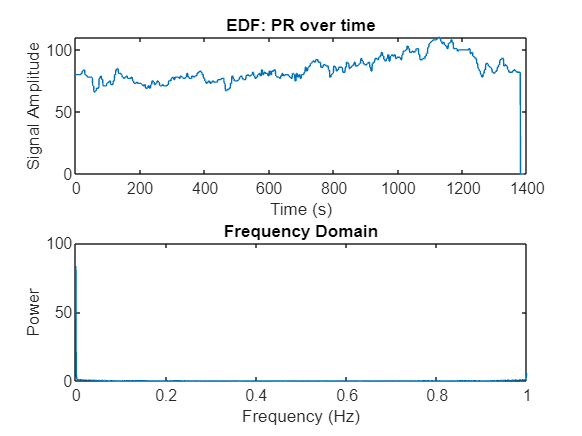


%% edf
signalEdf = edfFile1.PR; %the signal you want to convert
nEdf = length(signalEdf);
freqRangeEdf = (0:nEdf-1)*(edfSamplePeriod/nEdf); % frequency range
fftEdf = fft(signalEdf)/nEdf; % Fourier transform
powerEdf = abs(fftEdf); % power spectrum

figure
subplot(2,1,1)
plot(edfDuration, signalEdf)
xlabel('Time (s)')
ylabel('Signal Amplitude')
title('EDF: PR over time')

subplot(2,1,2)
plot(freqRangeEdf,powerEdf)
xlabel('Frequency (Hz)')
ylabel('Power')
title('Frequency Domain')


display('Fourier transforms: done');

Fourier transforms: done


## upsample gdt

upFactor=edfSampleRate/gdtSampleRate;
upGdt = interp(signalGdt, upFactor);
length(upGdt)

ans = 960

length(signalGdt)

ans = 96

upGDTDuration = interp(gdtDuration, upFactor);
dt = mean(diff(upGDTDuration)); %foute waarde? foute manier, eventueel interp gebruiken
up_Fs  = 1 / dt; %sampling frequency gdt
up_period = 1/up_Fs; %sampling period
n = length(upGdt);
f = (0:n-1)*(up_Fs/n); % frequency range
Y = fft(upGdt)/n; % Fourier transform
powerUpGdt = abs(Y); % power spectrum
display('upsampling gdt: done');

upsampling gdt: done


## cross correlation

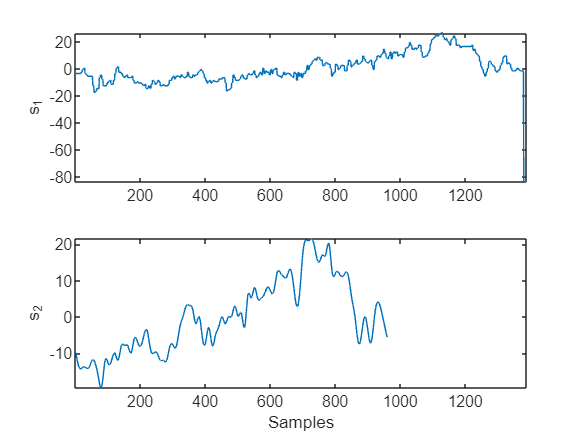

s1=signalEdf;
s1=s1-mean(s1);
%remove dc offset
s2=upGdt;
s2=s2-mean(s2);

ax(1) = subplot(2,1,1);
plot(s1)
ylabel('s_1')
axis tight

ax(2) = subplot(2,1,2);
plot(s2)
ylabel('s_2')
axis tight

xlabel('Samples')

linkaxes(ax,'x')

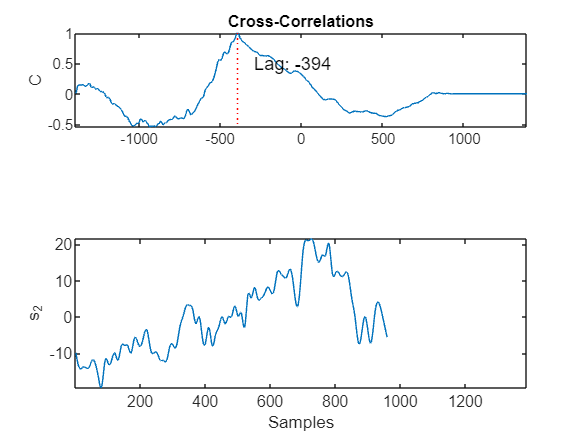


[C,lags] = xcorr(s2,s1);
C = C/max(C);%normalize

[M,I] = max(C);
t = lags(I);

subplot(3,1,1)
plot(lags,C,[t t],[-0.5 1],'r:')
text(t+100,0.5,['Lag: ' int2str(t)])
ylabel('C')
axis tight
title('Cross-Correlations')

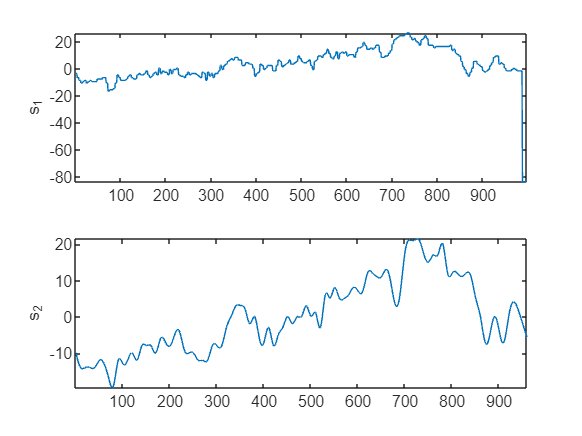


edf_cor = s1(-t:end);

ax(1) = subplot(2,1,1);
plot(edf_cor)
ylabel('s_1')
axis tight

ax(2) = subplot(2,1,2);
plot(s2)
ylabel('s_2')
axis tight

## plot together

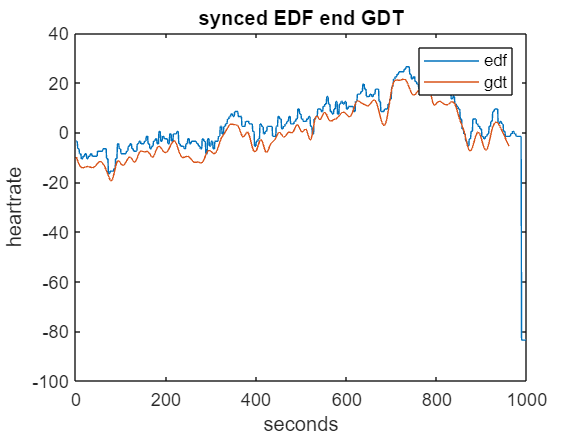

figure
plot(edf_cor)
hold on
plot (s2)
ylabel('heartrate')
xlabel('seconds')
title('synced EDF end GDT')
legend('edf','gdt')
hold off

## calculate maximum and minimum

maxValueEdf=max(edf_cor)

maxValueEdf = 26.4313

maxTimeEdf = find(edf_cor == maxValueEdf)

maxTimeEdf =    732
   733
   734
   735
   736
   737
   738
   739


minValueEdf=min(edf_cor)

minValueEdf = -83.5687

minTimeEdf = find(edf_cor == minValueEdf)

minTimeEdf =    988
   989
   990
   991
   992
   993
   994
   995
   996
   997



maxValueGdt=max(s2)

maxValueGdt = 21.4370

maxTimeGdt = find(s2 == maxValueGdt)

maxTimeGdt = 727

minValueGdt=min(s2)

minValueGdt = -19.3949

minTimeGdt = find(s2 == minValueGdt)

minTimeGdt = 78

## calulate engery consumed

%mean(load)*duration
%calc calories from joules


## write to csv

%csvwrite(re)